# Tabletop Lab

BMP211 - Fall 2022

In this part of the lab we will look at how undersampling k-space in different ways impacts the image. We have provided fft2c and ifft2c as Fourier transform function to call in order to perform the fourier transform operations.

clear all
close all

## Dataset

We will load in a T1-weighted brain image from a high-resolution dataset as a part of a larger study that achieved high-quality, 760µm resolution whole brain diffusion images. The source for this file is from: 

Wang, Fuyixue et al. (2022), Data from: In vivo human whole-brain Connectom diffusion MRI dataset at 760 µm isotropic resolution (PART I), Dryad, Dataset, [https://doi.org/10.5061/dryad.nzs7h44q2](https://doi.org/10.5061/dryad.nzs7h44q2)

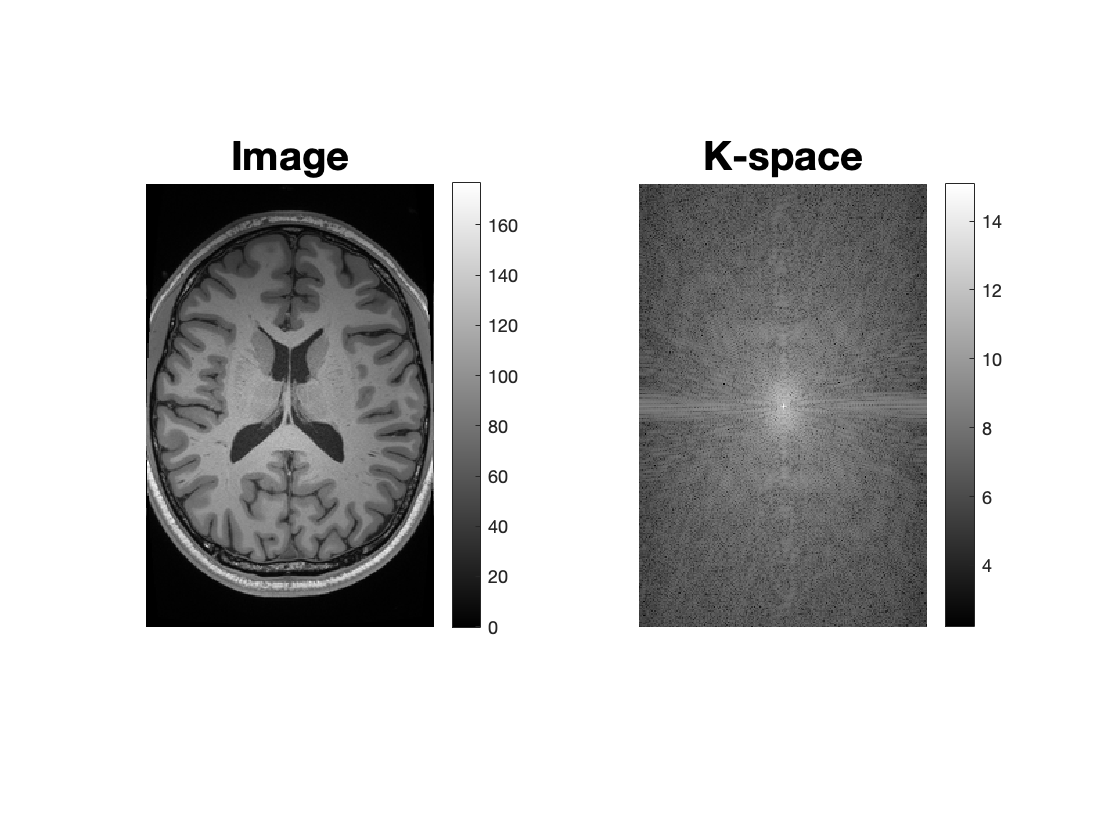

%Load in Whole brain
whole_brain = niftiread('T1brain.nii.gz');
% Let's use one slice of the brain
brain_slice = flip(whole_brain(:,1:320,240),2)';
% We can take the fourier transform to visualize the k-space
kspace = fft2c(brain_slice);

% Size of matrix to be used for later
matrix_size = size(kspace);
sizex = matrix_size(1);
sizey = matrix_size(2);

% Plot the brain
figure;
subplot(1,2,1);
% Plot the brain slice
imagesc(brain_slice);axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()
subplot(1,2,2);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()

## Undersampling K-space

Instead of acquiring undersampled data, we will modify this dataset and “simulate” undersampling conditions. In other words, we can create “mask” matrices that consist of 1s and 0s and multiply it with our k-space data to simulate undersampling. This will delete the lines with the 0s and keep the ones with 1s. Let's see what happens if we mask our k-space in different ways.

**Q17: Zero every other row in k-space and display the resultant k-space and the image. Comment on the image you reconstruct.**

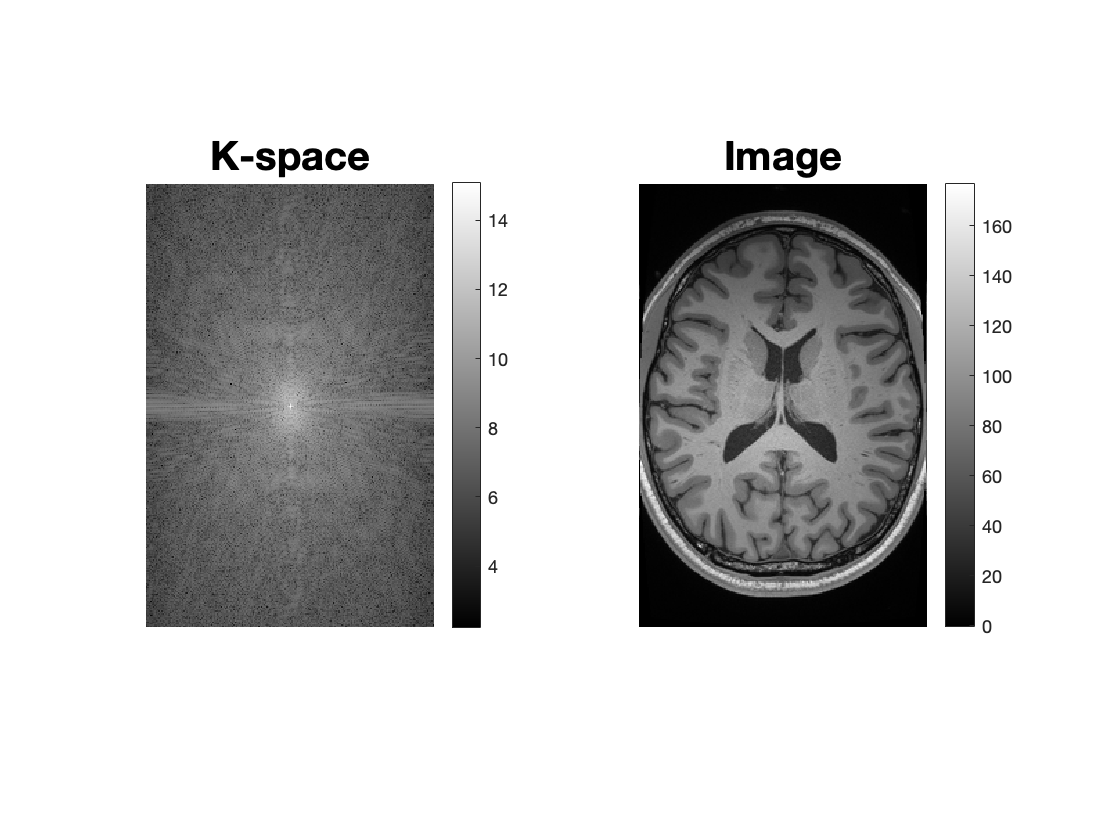

%%%%%%%%%%%%%%%%%%%%%%%%% Fill In!
% Set up mask and apply to k-space

masked_kspace = kspace; % Replace with your masked kspace

% New image
new_image = brain_slice; % Replace with your masked image

%%%%%%%%%%%%%%%%%%%%%%%%%

% Disply New K-space and Image
figure;
subplot(1,2,1);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(masked_kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()
subplot(1,2,2);
% Plot the brain slice
imagesc(new_image);axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()

**Q18: Zero every other column in k-space and display the resultant k-space and the image. Comment on the image you reconstruct.**

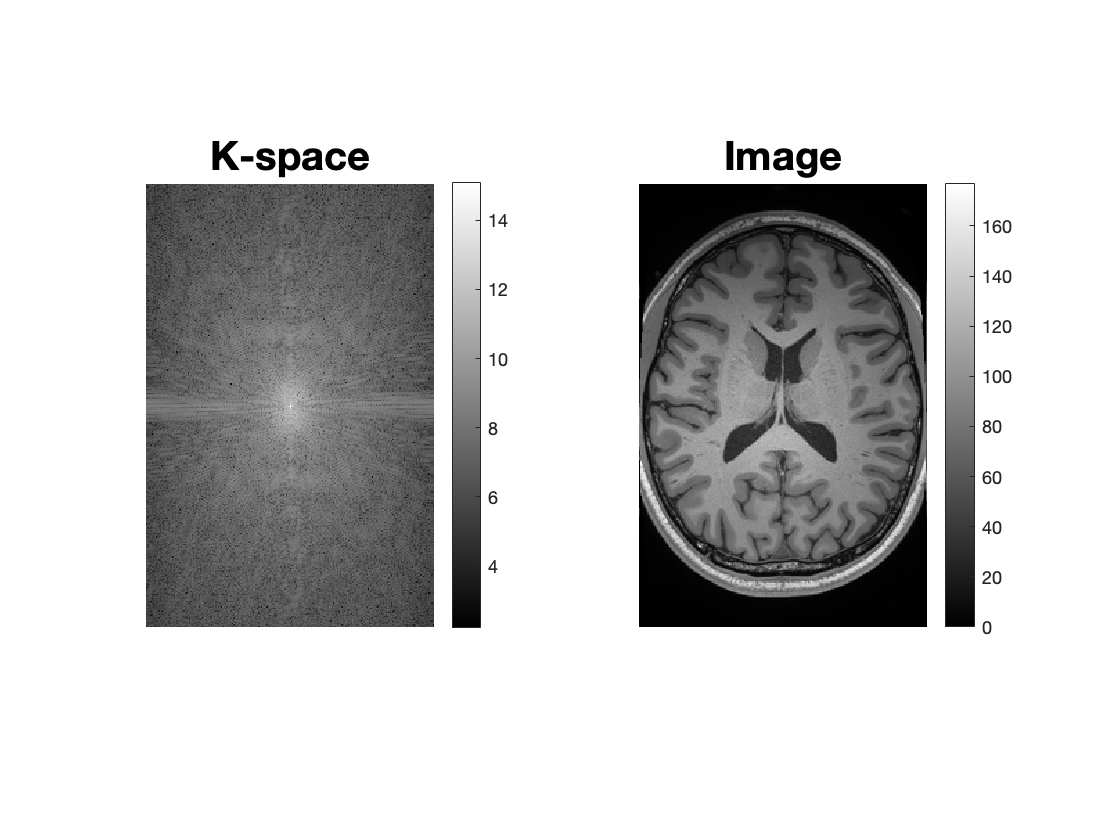

%%%%%%%%%%%%%%%%%%%%%%%%% Fill In!
% Set up mask and apply to k-space

masked_kspace = kspace; % Replace with your masked kspace

% New image
new_image = brain_slice; % Replace with your masked image

%%%%%%%%%%%%%%%%%%%%%%%%%

% Disply New K-space and Image
figure;
subplot(1,2,1);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(masked_kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()
subplot(1,2,2);
% Plot the brain slice
imagesc(abs(new_image));axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()

**Q19: Zero 2/3 of the k-space columns (keep one column, zero 3 columns) and display the resultant k-space and the image. Comment on the image you reconstruct.**

%%%%%%%%%%%%%%%%%%%%%%%%% Fill In!
% Set up mask and apply to k-space

masked_kspace = kspace; % Replace with your masked kspace

% New image
new_image = brain_slice; % Replace with your masked image

%%%%%%%%%%%%%%%%%%%%%%%%%

% Disply New K-space and Image
figure;
subplot(1,2,1);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(masked_kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()
subplot(1,2,2);
% Plot the brain slice
imagesc(abs(new_image));axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()

## Lowpass/ High Pass Filters

K-space is the 2D spatial frequency domain. Different frequency encode different types of information. We are going to investigate the role of low and high frequencies in the reconstruction of an image. We can isolate the two components by designing filters that keep only the frequencies we are interested in. Low-pass filters remove all the high frequencies leaving only low frequencies, and High-pass filters perform in the opposite manner. Therefore, we will apply a low-pass and high-pass filter to the image. 

**Q20: Zero the center 50% of the k-space. Take the inverse Fourier transform and display your image. Comment on how this image compares to the original. **

%%%%%%%%%%%%%%%%%%%%%%%%% Fill In!
% Set up mask and apply to k-space

masked_kspace = kspace; % Replace with your masked kspace

% New image
new_image = brain_slice; % Replace with your masked image

%%%%%%%%%%%%%%%%%%%%%%%%%

% Disply New K-space and Image
figure;
subplot(1,2,1);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(masked_kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()
subplot(1,2,2);
% Plot the brain slice
imagesc(abs(new_image));axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()

**Q21: Zero the outer 50% of the k-space. Take the inverse Fourier transform and display your image. Comment on how this image compares to the original. **

%%%%%%%%%%%%%%%%%%%%%%%%% Fill In!
% Set up mask and apply to k-space

masked_kspace = kspace; % Replace with your masked kspace

% New image
new_image = brain_slice; % Replace with your masked image

%%%%%%%%%%%%%%%%%%%%%%%%%

% Disply New K-space and Image
figure;
subplot(1,2,1);
% We plot the log magnitude of k-space to better visualize
imagesc(log(abs(masked_kspace)));
axis image; colormap gray; axis off;title('K-space','FontSize',20);colorbar()
subplot(1,2,2);
% Plot the brain slice
imagesc(abs(new_image));axis image; 
colormap gray; axis off;title('Image','FontSize',20);colorbar()